# Hour power 2

### Create temporary data structures for fft analysis of amplitude power at period frequency

Channel 1 - data normalized by: data.*1/trend

%channel 1
%list of good data from kg
goodkgidx1 = [1 2 54 6 7 8 101 10 11 12 14 15 16 19 27 31 100 28 30 33 35 36 37 38 39 40 41 42 54 56 58 59];
fortyeightidx1 = [3 4 5 44 46 49];

%resample rate
ReFs = 10;

%divide data into trials
  %48 hour trials
    for j = 1:length(goodkgidx1)
      gk148(j).trial1 = KatieTrialTrendDessembler(kg(goodkgidx1(j)), 1, 48, ReFs);
       %gk1(j).trial1 = KatieTrialTrendDessembler(kg(goodkgidx1(j)), 1, 48, ReFs);
    end
    

  %96 hour tirals
    for j = 1:length(fortyeightidx1)
      gk196(j).trial1 = KatieTrialTrendDessembler(kg(fortyeightidx1(j)), 1, 96, ReFs);
    end
    
  %combine trial data 
    gk1 = [gk148 gk196];


  %perform fft of amplitude at period frequency
    for j = length(gk1):-1:1
        for jj = 1:length(gk1(j).trial1)
       [gk1(j).freq1(jj), gk1(j).pwr1(jj)] = k_welches(gk1(j).trial1(jj), gk1(j).trial1(jj).ld, ReFs);
       gk1(j).hour1(jj) = gk1(j).trial1(jj).ld;
        end
    end
    
    
  %perform fft of amplitude a 24 hour period frequency
    for j = length(gk1):-1:1
        for jj = 1:length(gk1(j).trial1)
       [gk1(j).twfreq1(jj), gk1(j).twpwr1(jj)] = k_welches(gk1(j).trial1(jj), 12, ReFs);
        end
    end
  

Raw spline data channel 1

%   
%     for j = 1:length(goodkgidx1)
%       rgk1(j).trial1 = KatieTrialTrendDessembler(kg(goodkgidx1(j)), 1, 48);
%     end
%     
%     for j = length(rgk1):-1:1
%         for jj = 1:length(rgk1(j).trial1)
%        [rgk1(j).freq1(jj), rgk1(j).pwr1(jj)] = k_welches(rgk1(j).trial1(jj), rgk1(j).trial1(jj).ld, 10);
%        rgk1(j).hour1(jj) = rgk1(j).trial1(jj).ld;
%         end
%     end
% 


%channel 2
%list of good data from kg
goodkgidx2 = [1 55 6 7 10 11 12 14 15 16 19 30 31 28 33 35 36 37 38 39 40 41 42 47 98 55 57 97 96 59];
fortyeightidx2 = [3 4 5 44 45 46 49];

%divide data into trials
  %48 hour trials
    for j = length(goodkgidx2):-1:1
      gk248(j).trial2 = KatieTrialTrendDessembler(kg(goodkgidx2(j)), 2, 48, ReFs);
      %gk2(j).trial2 = KatieTrialTrendDessembler(kg(goodkgidx2(j)), 2, 48);
    end
    
  %96 hour tirals
    for j = 1:length(fortyeightidx2)
      gk296(j).trial2 = KatieTrialTrendDessembler(kg(fortyeightidx2(j)), 1, 96, ReFs);
    end
    
  %combine trials   
    gk2 = [gk248 gk296];
    
  %perform fft of amplitude at period frequency  
    for j = length(gk2):-1:1
        for jj = 1:length(gk2(j).trial2)
       [gk2(j).freq2(jj), gk2(j).pwr2(jj)] = k_welches(gk2(j).trial2(jj), gk2(j).trial2(jj).ld, ReFs);
       gk2(j).hour2(jj) = gk2(j).trial2(jj).ld;
        end
    end
    
   %perform fft of amplitude at 24 hour period frequency  
    for j = length(gk2):-1:1
        for jj = 1:length(gk2(j).trial2)
       [gk2(j).twfreq2(jj), gk2(j).twpwr2(jj)] = k_welches(gk2(j).trial2(jj), 12, ReFs);
        end
    end
    
    
    

%raw spline data Channel 2    
%     for j = 1:length(goodkgidx2)
%       rgk2(j).trial2 = KatieTrialDessembler(kg(goodkgidx2(j)), 2, 48);
%     end
%     
%     for j = length(rgk2):-1:1
%         for jj = 1:length(rgk2(j).trial2)
%        [rgk2(j).freq2(jj), rgk2(j).pwr2(jj)] = k_welches(rgk2(j).trial2(jj), rgk2(j).trial2(jj).ld, 10);
%        rgk2(j).hour2(jj) = rgk2(j).trial2(jj).ld;
%         end
%     end

# Plots

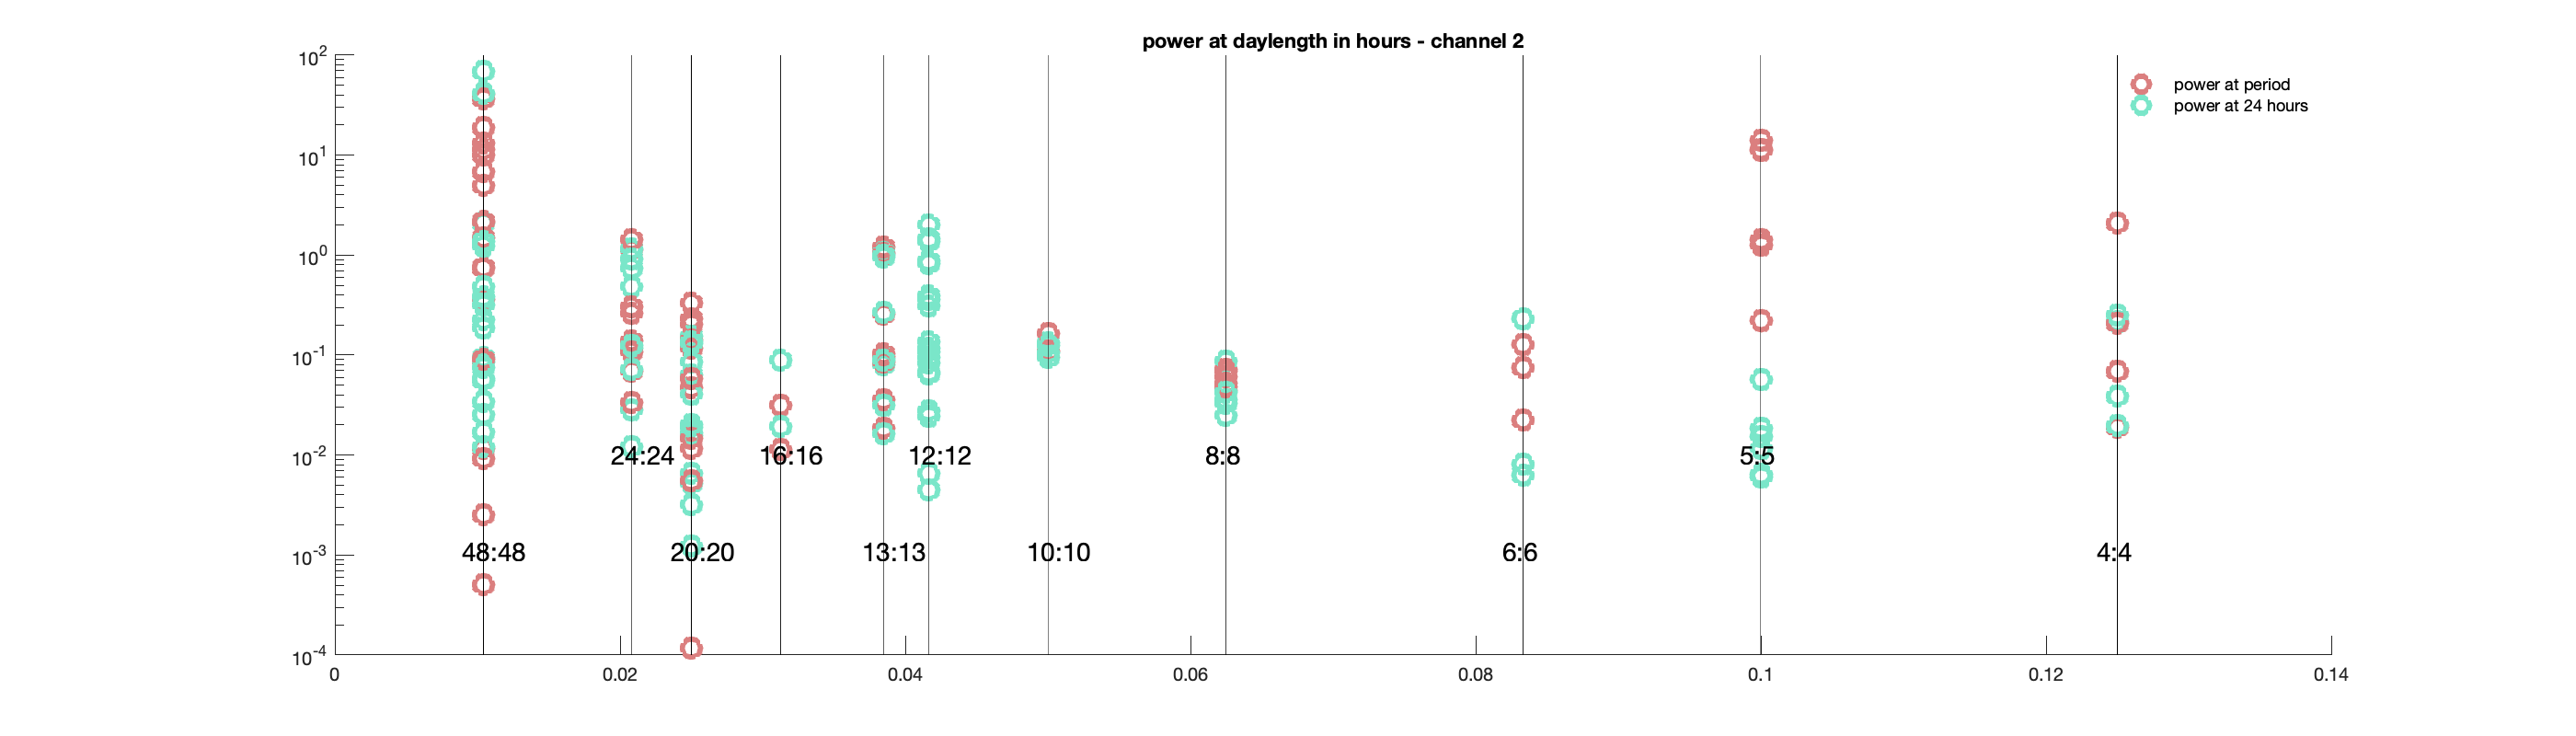

%colors for plots
rosey = [.8588 0.4980 0.4980];
aqua = [0.4784 0.9020 0.7882];
        
%size of figure window
L = 2*200;
W = 2*700; %changed from 2*420

figure(3); clf; hold on; title('power at daylength in hours - channel 2');
%set(figure(1),'Units','normalized','Position',[0 0 .5 .5]); 
    set(gcf, 'Position', [0 0 W L]);

    
   
    %Draw lines for light cycles
    hrs = [96, 48, 40, 32, 26, 24, 20, 16, 12, 10, 8]; % Double hours

    %plot data on log scale
    %fftmachine
    
   
    for j = 1:length(gk2)
        for jj = 1:length(gk2(j).freq2)
            
            %plot amplitude power at period frequency
            plot(gk2(j).freq2(jj), gk2(j).pwr2(jj), 'o', 'Color', rosey, 'MarkerSize', 10, "LineWidth", 3); hold on;
            
%             %plot amplitude power at 24 hour period frequency
            plot(gk2(j).twfreq2(jj), gk2(j).twpwr2(jj), 'o', 'Color', aqua, 'MarkerSize', 10, "LineWidth", 3); hold on;
%             
            
            %for raw data comparison to trend normalization
            %plot(rgk2(j).freq2(jj),rgk2(j).pwr2(jj), 'o', 'Color', aqua, 'MarkerSize', 10, "LineWidth", 3); hold on;
        end
    end
         set(gca,'yscale', 'log');  
        legend('power at period','power at 24 hours', 'AutoUpdate','off');
        legend('boxoff')
        
        minY = min(ylim);
        maxY = max(ylim);
        for h=1:length(hrs)

            plot([1/hrs(h), 1/hrs(h)], ylim, 'k-', 'LineWidth', 0.25);
            
            label = num2str(hrs(h)/2);
            str = " " + label + ":" + label;
            
            if mod(h, 2) == 0 % j is even
                pos(h) = minY+ 0.01;
            else % j is odd
                pos(h) = minY + 0.001;
            end
            text(1/hrs(h)-0.002, pos(h), str, 'FontSize', 14);

        end

%               legend('Ch2','Ch1', 'AutoUpdate','off');
%               legend('boxoff')
       

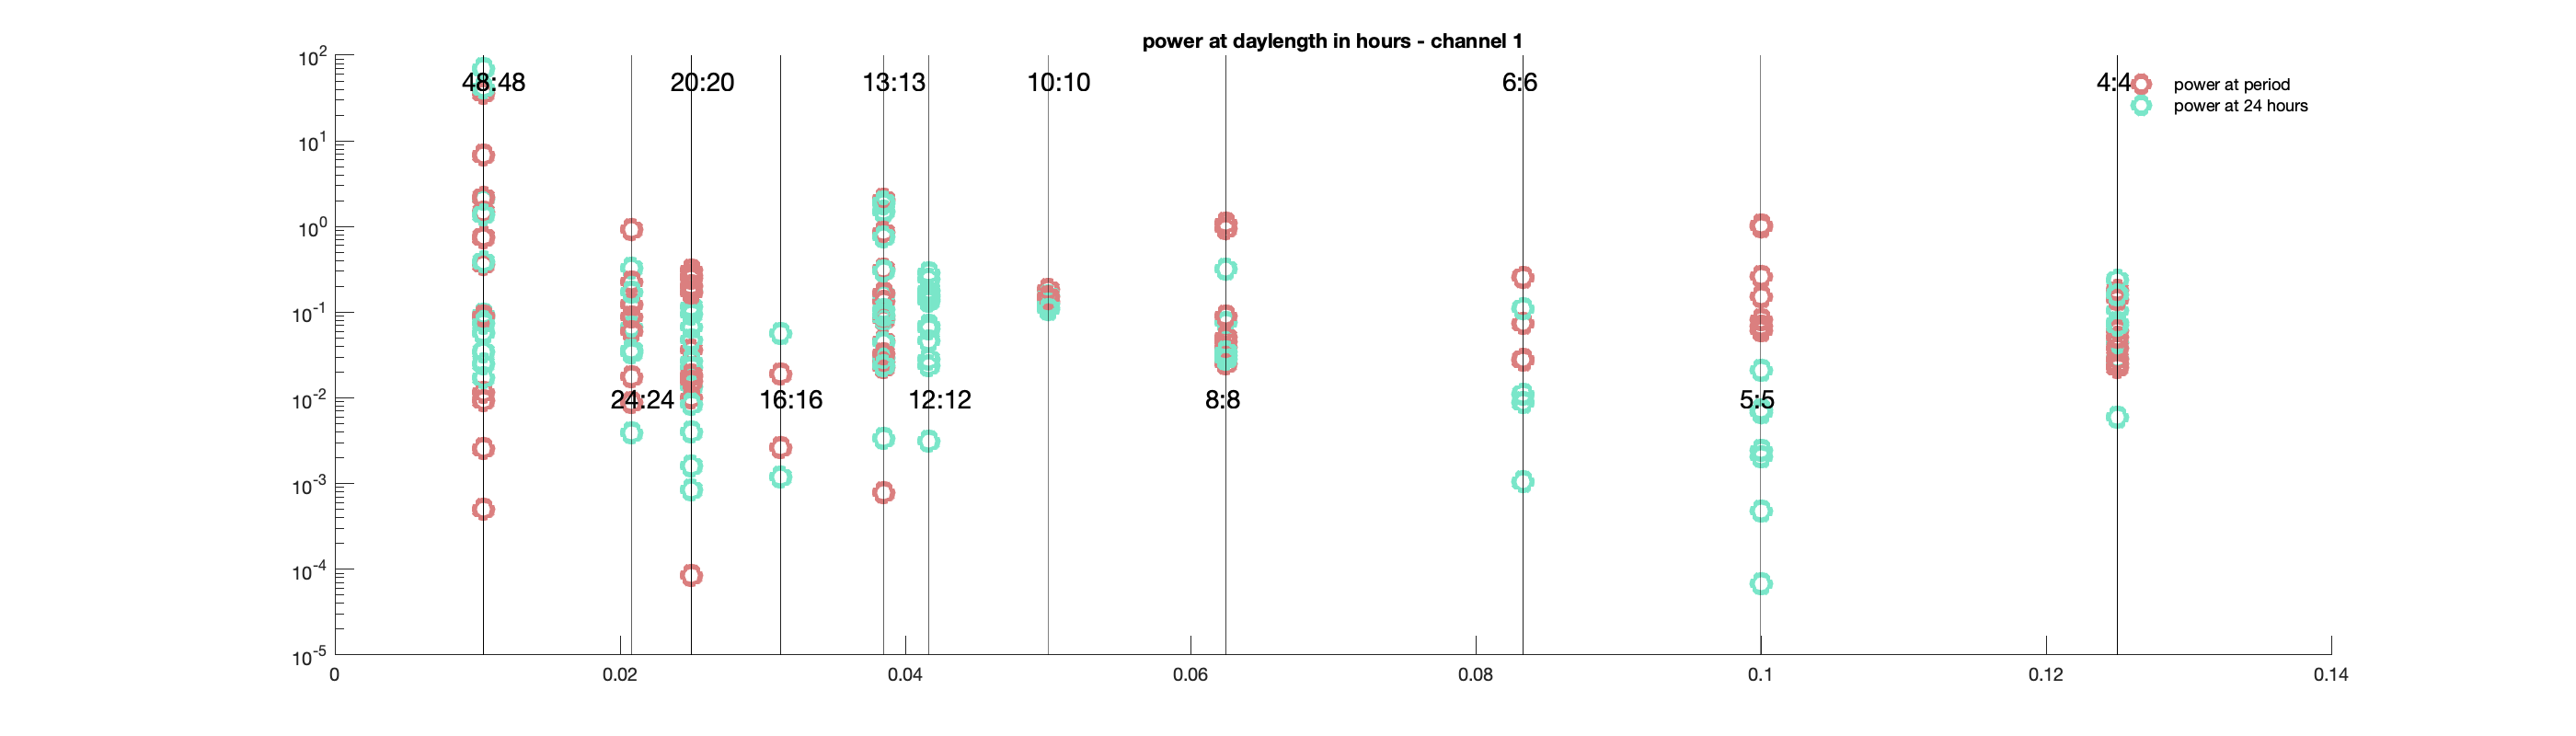

%colors for plots
rosey = [.8588 0.4980 0.4980];
aqua = [0.4784 0.9020 0.7882];
        
%size of figure window
L = 2*200;
W = 2*700; %changed from 2*420

figure(4); clf; hold on; title('power at daylength in hours - channel 1');
%set(figure(1),'Units','normalized','Position',[0 0 .5 .5]); 
    set(gcf, 'Position', [0 0 W L]);

   
   
    %Draw lines for light cycles
    hrs = [96, 48, 40, 32, 26, 24, 20, 16, 12, 10, 8]; % Double hours

    
    for k = 1:length(gk1)
        for kk = 1:length(gk1(k).freq1)
            
          %plot amplitude power at period frequency  
          plot(gk1(k).freq1(kk), gk1(k).pwr1(kk), 'o', 'Color', rosey, 'MarkerSize', 10, "LineWidth", 3);  %ylim([minY, maxY + 0.01]);
          
          %plot amplitude power at 24 hour period  
          plot(gk1(k).twfreq1(kk), gk1(k).twpwr1(kk), 'o', 'Color', aqua, 'MarkerSize', 10, "LineWidth", 3);
          
          
          %plot normalization against raw spline
          %plot(rgk1(k).freq1(kk), rgk1(k).pwr1(kk), 'o', 'Color', aqua, 'MarkerSize', 10, "LineWidth", 3); 
        end      
        
    end         
    
   set(gca,'yscale', 'log');
   legend('power at period','power at 24 hours', 'AutoUpdate','off');
        legend('boxoff')
        
        minY = min(ylim);
        maxY = max(ylim);
        
        for h=1:length(hrs)

            plot([1/hrs(h), 1/hrs(h)], ylim, 'k-', 'LineWidth', 0.25);
            label = num2str(hrs(h)/2);
            str = " " + label + ":" + label;
            if mod(h, 2) == 0 % j is even
                pos(j) = minY + 30;
            else % j is odd
                pos(h) = minY + 50 ;
            end
            text(1/hrs(h)-0.002, pos(h), str, 'FontSize', 14);

        end

Channel 1 vs channel 2 hourpower

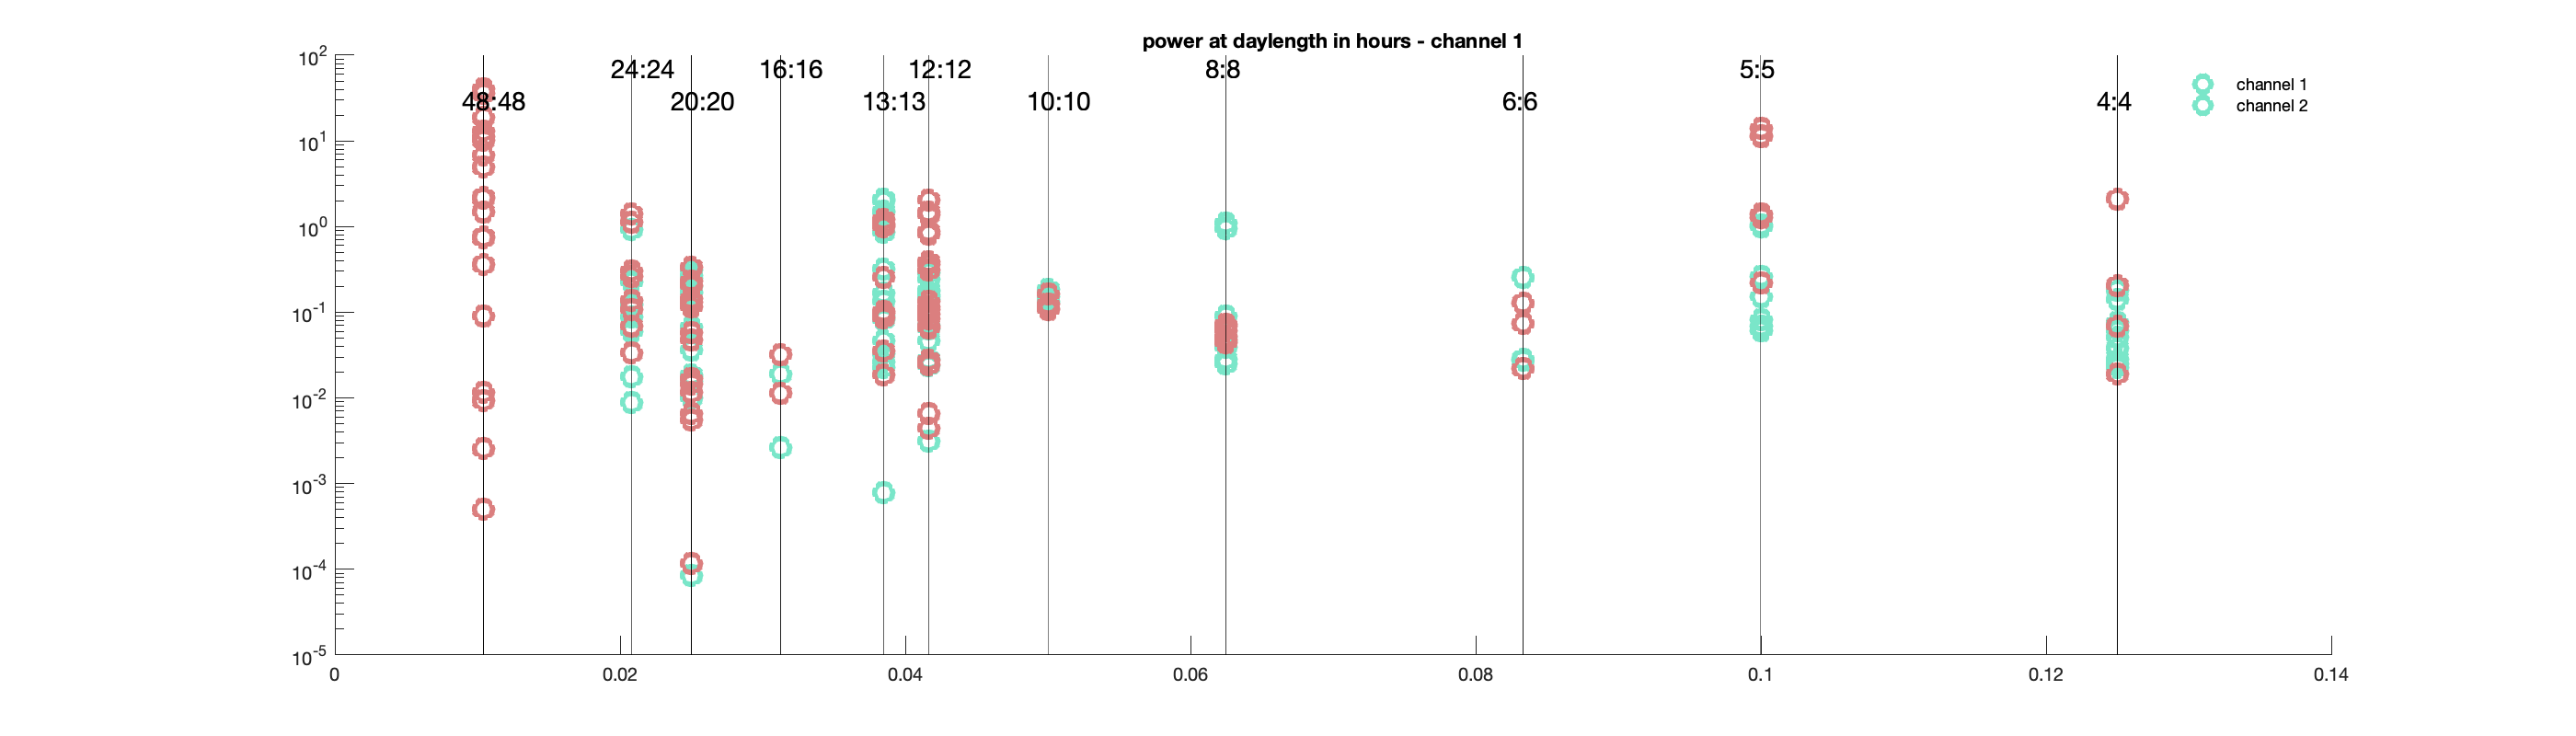

        
%colors for plots
rosey = [.8588 0.4980 0.4980];
aqua = [0.4784 0.9020 0.7882];
        
%size of figure window
L = 2*200;
W = 2*700; %changed from 2*420

figure(5); clf; hold on; title('power at daylength in hours - channel 1');
%set(figure(1),'Units','normalized','Position',[0 0 .5 .5]); 
    set(gcf, 'Position', [0 0 W L]);

   
   
    %Draw lines for light cycles
    hrs = [96, 48, 40, 32, 26, 24, 20, 16, 12, 10, 8]; % Double hours

    
    for k = 1:length(gk1)
        for kk = 1:length(gk1(k).freq1)
            
          %plot amplitude power at period frequency  
          plot(gk1(k).freq1(kk), gk1(k).pwr1(kk), 'o', 'Color', aqua, 'MarkerSize', 10, "LineWidth", 3);  %ylim([minY, maxY + 0.01]);
        end
        
    end    
    
    for j = 1:length(gk2)
        for jj = 1:length(gk2(j).freq2)
          %plot amplitude power at period frequency  
          plot(gk2(j).freq2(jj), gk2(j).pwr2(jj), 'o', 'Color', rosey, 'MarkerSize', 10, "LineWidth", 3);  %ylim([minY, maxY + 0.01]);
         
        end  
    end    
    
   set(gca,'yscale', 'log');
   
   
   legend('channel 1','channel 2', 'AutoUpdate','off');
        legend('boxoff');
        
        minY = min(ylim);
        maxY = max(ylim);
        
        for h=1:length(hrs)

            plot([1/hrs(h), 1/hrs(h)], ylim, 'k-', 'LineWidth', 0.25);
            label = num2str(hrs(h)/2);
            str = " " + label + ":" + label;
            if mod(h, 2) == 0 % j is even
                pos(h) = minY + 70;
            else % j is odd
                pos(h) = minY + 30 ;
            end
            text(1/hrs(h)-0.002, pos(h), str, 'FontSize', 14);

        end              